# B-mode reconstruction from k-Wave pre-beamformed RF data

El objetivo de este .mlx es entender como funciona la reconstruccion y visualizacion de la imagen B-mode a partir de los datos de radiofrecuencia generados por el pipeline de simulación proporcionado por el Laboratorio de Imágenes Médicas y como usarlo para visualizarlo en el pipeline generado.

Una imagen B-mode representa la amplitud de los ecos de ultrasonido en función de la posición dentro del plano de exploración. Sin embargo, esta representación se obtiene solamente después de procesar adecuadamente las señales de Radio Frequencia (RF). Por ello, la transformación que se estudiará será:

- Tx->prograpagacion->Rx->sensor_data->combineSensorData->rf_prebf

- channel data (RFprebf): RF multicanal, datos RX organizados por elementos, antes del receive beamforming.

- receive beamforming (RX_beamforming): El receive beamforming calcula cuánto debe desplazarse cada señal para que los ecos correspondientes a una misma posición espacial coincidan, es deicr.

%{
RF_prebf:
RX1          -------/\--------
RX2          ------/\---------
RX3          -----/\----------
RX4          ------/\---------
RX5          -------/\--------

delay_and_sum
RX1          -----/\----------
RX2          -----/\----------
RX3          -----/\----------
RX4          -----/\----------
RX5          -----/\----------

y obtenemos: RF scan line de esto.
%}


- scan lines (RFscanlines - A mode)

- transmit-signal suppression  (Tx)

- frequency filtering 

- envelope detection (hilbert)

- log compression

- B-mode

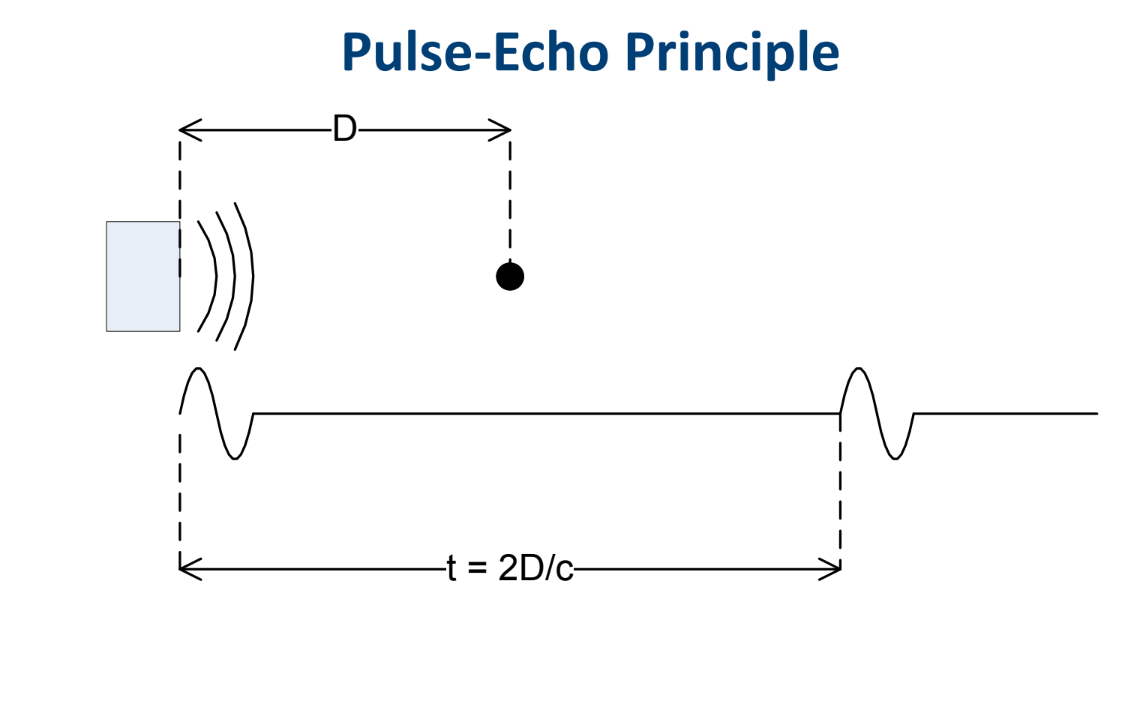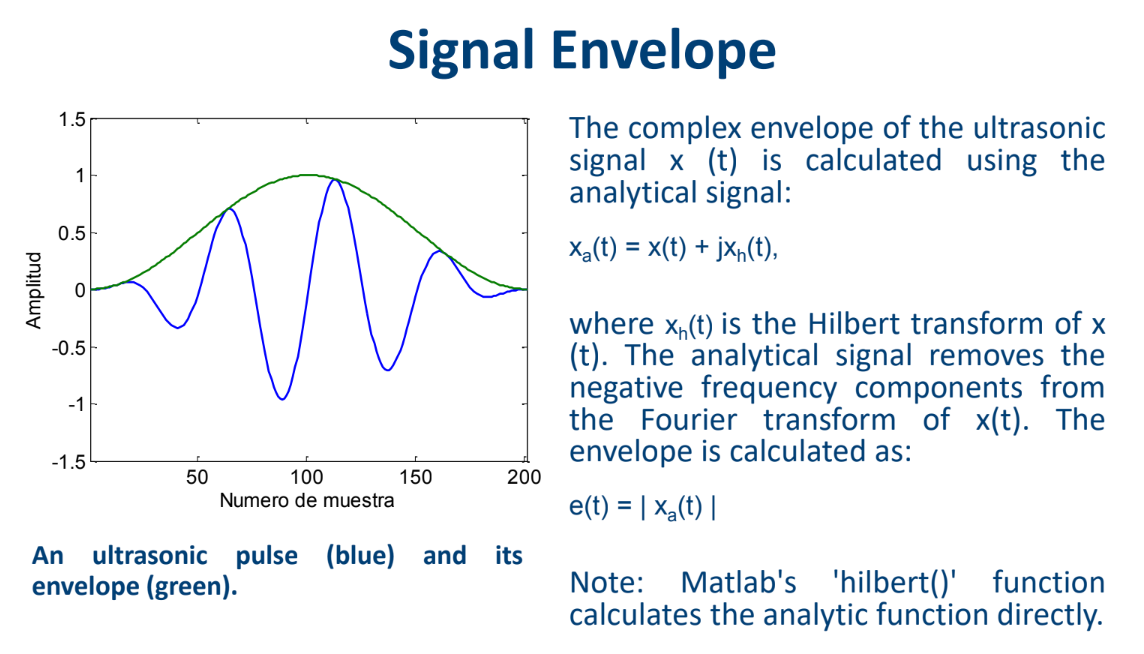

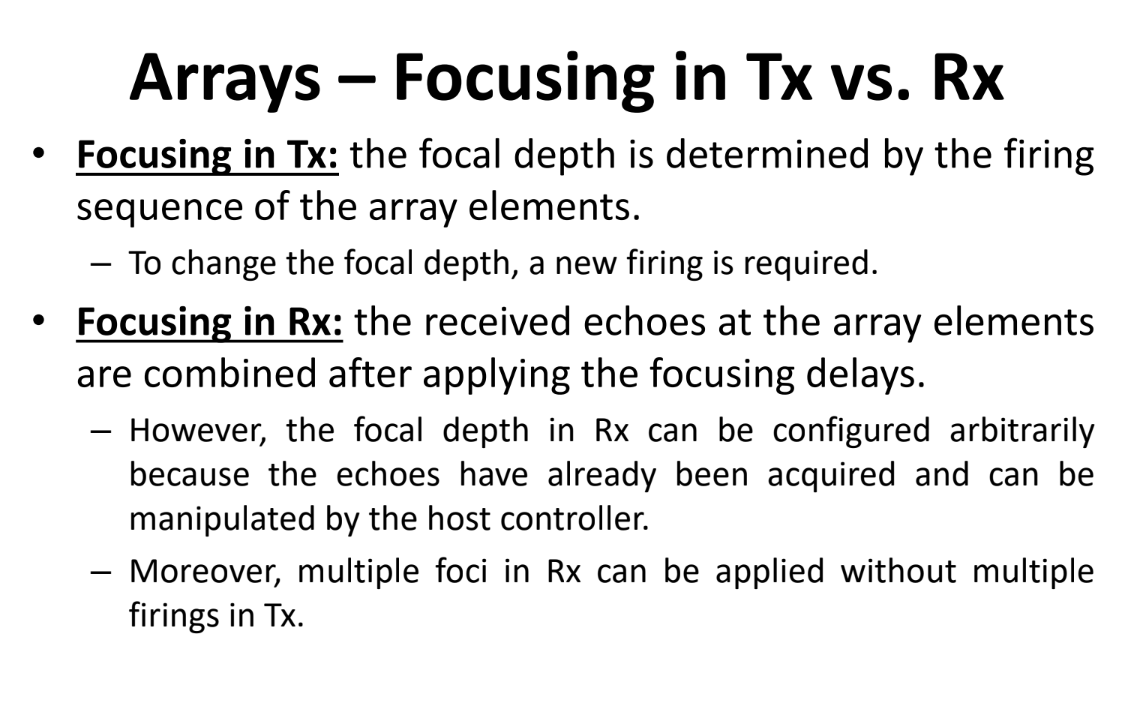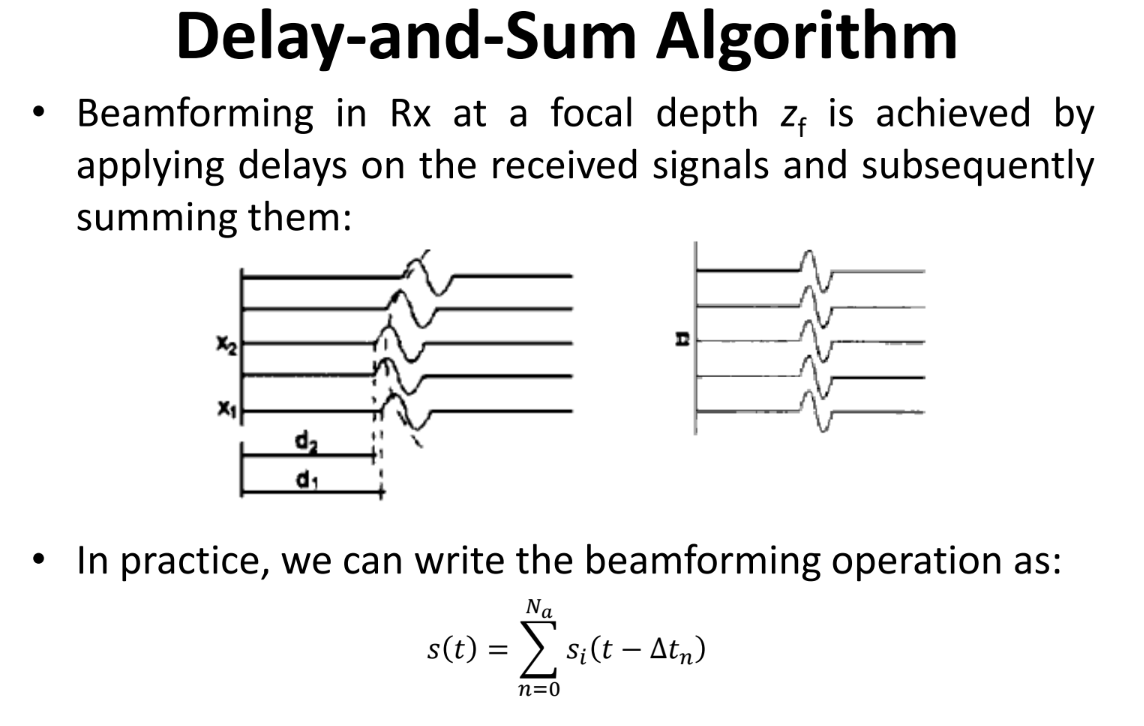

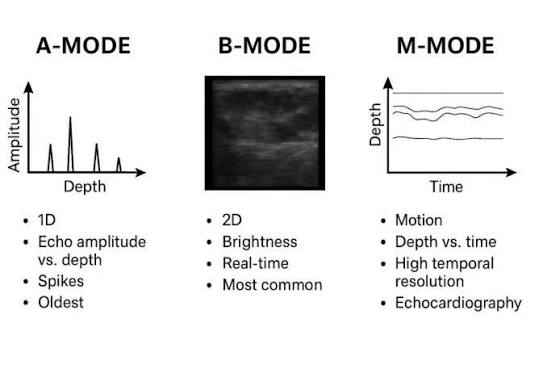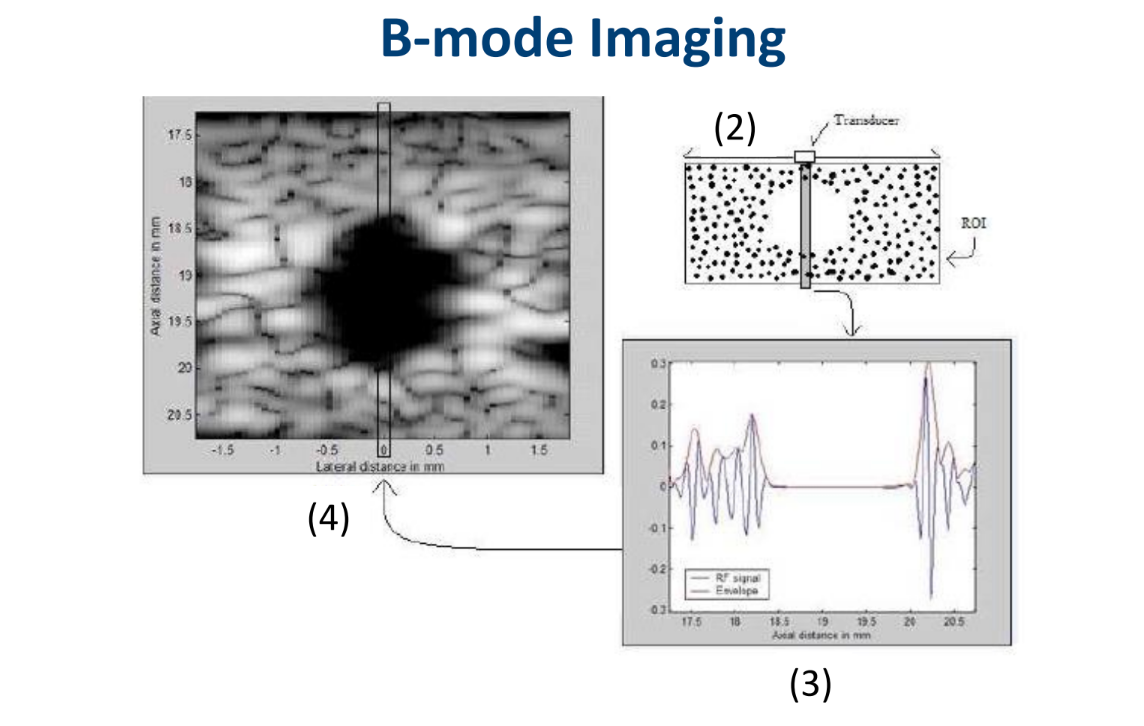

Sin embargo, el resultado de las simulaciones actuales todavía no es una imagen B-mode. El pipeline guarda una matriz que contiene **data RF**:

**rf_prebf = zeros(kgrid.Nt, element_num, nLines);**

donde "t" corresponde al tiempo, "e" al elemento receptor y "l" a la posición lateral o scan line.

*Esta instrucción pertenece al script generador y no debe ejecutarse durante el análisis del *`.mat`*, porque *`kgrid`* y *`element_num`* no se guardaron como variables independientes. Una vez cargado el resultado, las dimensiones deben obtenerse directamente de *`rf_prebf`*.*

Nota:

Durante la retroalimentación se indicó que el beamforming utilizado previamente por el laboratorio estaba adaptado específicamente a transmisiones enfocadas y que no debía interpretarse como un delay-and-sum genérico reutilizable directamente para todas las configuraciones de transmisión. Por este motivo, en este notebook se validará primero únicamente la reconstrucción correspondiente al caso focalizado actual. Ademas no se usa TGC, 

Asimismo, se recalca que el procesamiento será adaptado a la estructura de datos generada por el pipeline proporcionado por el LIM y a las recomendaciones recibidas durante las reuniones de retroalimentación.

En ese sentido cargamos el archivo .mat:

%% 1. Seleccionar dataset
[fileName, folderName] = uigetfile( ...
    '*.mat', ...
    'Selecciona rf_prebf');

if isequal(fileName, 0)

Dataset:
/Users/miguelisidrobaez/Desktop/Academico/Organización/LIM/DPB/dpb-qus-benchmark/docs/EXP_1_RESULTS/pipeline_ref/homogeneus_target_alpha0p8_std0p04/rf_prebf_homRef_001.mat



    error('No se seleccionó ningún archivo.');

  Name                    Size                    Bytes  Class     Attributes

  PMLSize                 1x2                        16  double              
  alpha_coeff          1402x1002               11238432  double              
  c0                      1x1                         8  double              
  cfl                     1x1                         8  double              
  density_map          1402x1002               11238432  double              
  density_std             1x1                         8  double              
  depth                   1x1                         8  double              
  dx                      1x1                         8  double              
  element_pitch           1x1                         8  double              
  element_width           1x1                         8  double              
  focal_number_Rx         1x1                         8  double              
  focal_number_Tx         1x1                         8  double

end

dataFile = fullfile(folderName, fileName);

fprintf('Dataset:\n%s\n\n', dataFile);
whos('-file', dataFile)
%% 2. Abrir RF + metadata

M = matfile(dataFile);

S = load(dataFile, ...
    'fs', ...
    'c0', ...

    'element_pitch', ...
    'source_focus', ...
    'source_f0', ...
    'source_cycles', ...
    'time_delays', ...
    'yCords');

rfSize = size(M, 'rf_prebf');

Nt        = 9187


Elements  = 66


Nt       = rfSize(1);

Lines     = 128


nElements = rfSize(2);

fs        = 133.20 MHz


nLines    = rfSize(3);

c0        = 1595.0 m/s



fprintf('Nt        = %d\n', Nt);
fprintf('Elements  = %d\n', nElements);
fprintf('Lines     = %d\n', nLines);
fprintf('fs        = %.2f MHz\n', S.fs/1e6);
fprintf('c0        = %.1f m/s\n', S.c0);


%% GENERADOR B-MODE

% ---------------------------------------------------------
% INTERFAZ
% ---------------------------------------------------------

experimentID = "REF";

prebfFile = "";

configFile = "";

DR = 60;


% =========================================================
% DESDE AQUÍ SE EJECUTA AL PULSAR "GENERAR B-MODE"
% =========================================================


Selecciona el archivo .mat que contiene rf_prebf.

%% Comprobar selección

if strlength(prebfFile) == 0
    error('Selecciona el archivo .mat que contiene rf_prebf.');
end

if strlength(configFile) == 0
    error('Selecciona el archivo .mat de configuración/pipeline.');
end


%% 1. Cargar experimento

B = loadBModeExperiment(prebfFile, configFile);


%% 2. Receive beamforming

fprintf('Generando B-mode de: %s\n', experimentID);
fprintf('Beamforming de %d líneas...\n', B.nLines);

rf_beamformed = zeros(B.Nt, B.nLines, 'single');

for iLine = 1:B.nLines

    % RF de una transmisión / scan line
    % [Nt x nElements]
    rfRaw = B.rfMat.rf_prebf(:,:,iLine);

    % DAS receive beamforming
    scanLine = receiveBeamformFixedFocus( ...
        rfRaw, ...
        B.fs, ...
        B.c0, ...
        B.element_pitch, ...
        B.source_focus);

    rf_beamformed(:,iLine) = single(scanLine);

end

fprintf('Receive beamforming terminado.\n');


%% 3. Suprimir región inicial correspondiente al TX

nBlank = 0;

if ~isempty(B.source_cycles) && ~isempty(B.source_f0)

    txDuration = B.source_cycles / B.source_f0;

    % Si existen delays TX, incluirlos
    if ~isempty(B.time_delays)
        txDuration = txDuration + max(B.time_delays(:));
    end

    nBlank = ceil(txDuration * B.fs);
    nBlank = min(nBlank, B.Nt);

    rf_beamformed(1:nBlank,:) = 0;

end


%% 4. Envelope detection

envelope = abs(hilbert(double(rf_beamformed)));


%% 5. Normalización

maxEnvelope = max(envelope(:));

if maxEnvelope <= 0
    error('La envolvente resultó vacía o con amplitud cero.');
end

envelopeNorm = envelope / maxEnvelope;


%% 6. Log compression

bmode = 20*log10(envelopeNorm + eps);

bmode(bmode < -DR) = -DR;


%% 7. Eje axial

t = (0:B.Nt-1)' / B.fs;

z = B.c0 * t / 2;      % [m]
z_mm = z * 1e3;


%% 8. Quitar de la visualización la región TX

validDepth = true(B.Nt,1);

if nBlank > 0
    validDepth(1:nBlank) = false;
end


%% 9. Eje lateral

if ~isempty(B.yCords) && numel(B.yCords) == B.nLines

    x = B.yCords(:).' * 1e3;     % mm
    xLabelText = 'Lateral position [mm]';

else

    % Todavía no inventamos coordenadas físicas
    x = 1:B.nLines;
    xLabelText = 'Scan line';

end


%% 10. MOSTRAR B-MODE

figure('Color','w');

imagesc( ...
    x, ...
    z_mm(validDepth), ...
    bmode(validDepth,:) );

colormap(gray(256));

clim([-DR 0]);

set(gca,'YDir','reverse');

xlabel(xLabelText);
ylabel('Depth [mm]');

title(sprintf('B-mode | %s | DR = %d dB', ...
    experimentID, DR));

cb = colorbar;
cb.Label.String = 'Amplitude [dB]';

axis tight;

fprintf('B-mode generado correctamente.\n');